# **BIO434: Intro to Preprocessing and EEG Data Analysis**

%% BIO434: Human Electrophysiology
% Data preprocessing and analyses in frequency space part 1
% Teacher: Vanessa Kasties, vanessa.kasties@kispi.uzh.ch
% v1.0, 14.12.2023

% a clean workspace for a fresh mind
clear
close all
clc

% path to data
mydata = 'C:/Users/vakas/switchdrive/BIO434/example-data/' %replace by your path

mydata = 'C:/Users/vakas/switchdrive/BIO434/example-data/'

## **Step 1: Filtering and Downsampling**

We will first generate a mixture of sine waves to see how different filters will affect our signal

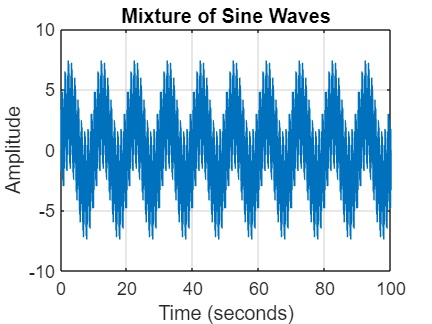

% Define the time vector
tp = 0:0.002:100; % Time vector from 0 to 100 seconds with a sampling interval of 0.002 seconds (sampling rate of 500 Hz)

% Define frequencies of sine waves
frequencies = [0.1, 1, 12, 25, 30]; % Frequencies in Hz
amplitudes = [3, 2, 1, 2, 0.5];
% try to define your own sine waves!

% Generate the mixture of sine waves
signal = zeros(size(tp)); % Initialize the signal vector

for i = 1:length(frequencies)
    % Add the sine wave to the signal
    signal = signal + amplitudes(i) * sin(2 * pi * frequencies(i) * tp);
end

% Plot the mixture of sine waves
figure;
plot(tp, signal);
title('Mixture of Sine Waves');
xlabel('Time (seconds)');
ylabel('Amplitude');
grid on;

Now let's design some filters

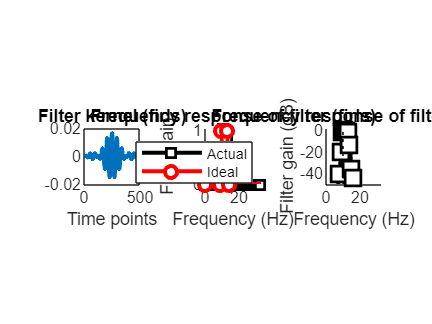

% filter parameters band-pass filter
srate   = 500; % hz
nyquist = srate/2; %Nyquist frequency
frange  = [10 13]; %frange = filter range, i.e., cutoff frequencies
transw  = .1; %transw = transition zone --> the sharper the edge, the more ringing artifacts
oFactor = 10;
order   = round(oFactor*srate/frange(1) ); % filter order = number of timepoints of filter kernel --> determines frequency resolution of filter
% minimal filter length: must contain at least one cycle of the lowest
% frequency, i.e. 1/10 = 100 ms 

% play around with the filter parameters to see what effect they have!

shape   = [ 0 0 1 1 0 0 ];
frex    = [ 0 frange(1)-frange(1)*transw frange frange(2)+frange(2)*transw nyquist ] / nyquist;


% filter kernel (representation in time domain - this is what signal is
% convolved with, length should change with filter order)
bpfiltkern = firls(order,frex,shape);
% compute the power spectrum of the filter kernel (frequency representation
% - check what part of the signal is dampened)
bpfiltpow = abs(fft(bpfiltkern)).^2;
% compute the frequencies vector and remove negative frequencies
hz      = linspace(0,srate/2,floor(length(bpfiltkern)/2)+1);
bpfiltpow = bpfiltpow(1:length(hz));


figure(1), clf
subplot(131)
plot(bpfiltkern,'linew',2)
xlabel('Time points')
title('Filter kernel (firls)')
axis square


% plot power spectrum of the filter kernel
subplot(132), hold on
plot(hz,bpfiltpow,'ks-','linew',2,'markerfacecolor','w')
plot(frex*nyquist,shape,'ro-','linew',2,'markerfacecolor','w')


% make the plot look nicer
set(gca,'xlim',[0 frange(2)+20])
xlabel('Frequency (Hz)'), ylabel('Filter gain')
legend({'Actual';'Ideal'})
title('Frequency response of filter (firls)')
axis square


% Same as above but in log-scale
subplot(133), hold on
plot(hz,10*log10(bpfiltpow),'ks-','linew',2,'markersize',10,'markerfacecolor','w')
plot([1 1]*frange(1),get(gca,'ylim'),'k:')
set(gca,'xlim',[0 frange(2)+20],'ylim',[-50 2])
xlabel('Frequency (Hz)'), ylabel('Filter gain (dB)')
title('Frequency response of filter (firls)')
axis square

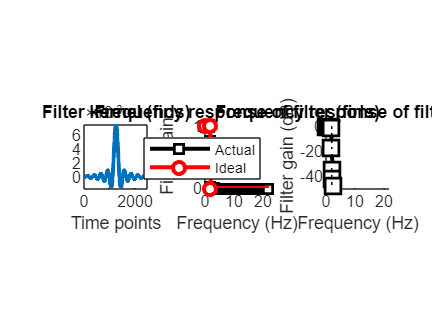

% filter parameters low-pass filter
srate   = 500; % hz
nyquist = srate/2;
cutoff = 2;
transw  = .1;
oFactor = 10;
order   = round(oFactor*srate/cutoff);
% play around with the filter parameters to see what effect they have!

shape   = [ 1 1 0 0 ];
frex    = [ 0 cutoff-cutoff*transw cutoff nyquist ] / nyquist;

% filter kernel
lpfiltkern = firls(order,frex,shape);
% compute the power spectrum of the filter kernel
lpfiltpow = abs(fft(lpfiltkern)).^2;
% compute the frequencies vector and remove negative frequencies
hz      = linspace(0,srate/2,floor(length(lpfiltkern)/2)+1);
lpfiltpow = lpfiltpow(1:length(hz));


figure(1), clf
subplot(131)
plot(lpfiltkern,'linew',2)
xlabel('Time points')
title('Filter kernel (firls)')
axis square


% plot power spectrum of the filter kernel
subplot(132), hold on
plot(hz,lpfiltpow,'ks-','linew',2,'markerfacecolor','w')
plot(frex*nyquist,shape,'ro-','linew',2,'markerfacecolor','w')


% make the plot look nicer
set(gca,'xlim',[0 cutoff+20])
xlabel('Frequency (Hz)'), ylabel('Filter gain')
legend({'Actual';'Ideal'})
title('Frequency response of filter (firls)')
axis square


% Same as above but in log-scale
subplot(133), hold on
plot(hz,10*log10(lpfiltpow),'ks-','linew',2,'markersize',10,'markerfacecolor','w')
plot([1 1]*cutoff,get(gca,'ylim'),'k:')
set(gca,'xlim',[0 cutoff+20],'ylim',[-50 2])
xlabel('Frequency (Hz)'), ylabel('Filter gain (dB)')
title('Frequency response of filter (firls)')
axis square

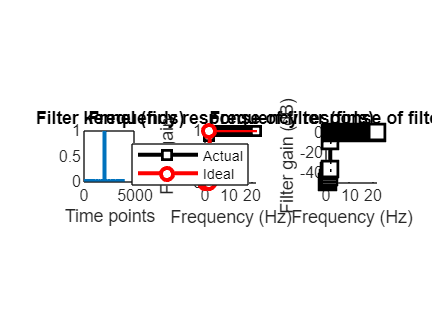

% filter parameters high-pass filter
srate   = 500; % hz
nyquist = srate/2;
cutoff  = 2;
transw  = .1;
oFactor = 16;
order   = round(oFactor*srate/cutoff);
% play around with the filter parameters to see what effect they have!

shape   = [ 0 0 1 1 ];
frex    = [ 0 cutoff-cutoff*transw cutoff nyquist ] / nyquist;

% filter kernel
hpfiltkern = firls(order,frex,shape);
% compute the power spectrum of the filter kernel
hpfiltpow = abs(fft(hpfiltkern)).^2;
% compute the frequencies vector and remove negative frequencies
hz      = linspace(0,srate/2,floor(length(hpfiltkern)/2)+1);
hpfiltpow = hpfiltpow(1:length(hz));


figure(1), clf
subplot(131)
plot(hpfiltkern,'linew',2)
xlabel('Time points')
title('Filter kernel (firls)')
axis square


% plot power spectrum of the filter kernel
subplot(132), hold on
plot(hz,hpfiltpow,'ks-','linew',2,'markerfacecolor','w')
plot(frex*nyquist,shape,'ro-','linew',2,'markerfacecolor','w')


% make the plot look nicer
set(gca,'xlim',[0 cutoff+20])
xlabel('Frequency (Hz)'), ylabel('Filter gain')
legend({'Actual';'Ideal'})
title('Frequency response of filter (firls)')
axis square


% Same as above but in log-scale
subplot(133), hold on
plot(hz,10*log10(hpfiltpow),'ks-','linew',2,'markersize',10,'markerfacecolor','w')
plot([1 1]*cutoff,get(gca,'ylim'),'k:')
set(gca,'xlim',[0 cutoff+20],'ylim',[-50 2])
xlabel('Frequency (Hz)'), ylabel('Filter gain (dB)')
title('Frequency response of filter (firls)')
axis square

Apply the filters to the signal and plot the outcome

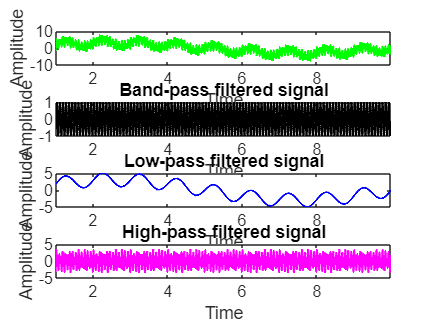

% apply the filter kernel to the signal
bpfiltsig = filtfilt(bpfiltkern,1,signal);
lpfiltsig = filtfilt(lpfiltkern,1,signal);
hpfiltsig = filtfilt(hpfiltkern,1,signal);

% plot the signal in the time domain (first 10 seconds only)
figure
subplot(411)
plot(tp(1:5000), signal(1:5000),'g','linew',1)
xlabel('Time'), ylabel('Amplitude')
set(gca,'xlim',[1 tp(5000)])

% plot time series
subplot(412)
plot(tp(1:5000), bpfiltsig(1:5000),'k','linew',1)
xlabel('Time'), ylabel('Amplitude')
title('Band-pass filtered signal')
set(gca,'xlim',[1 tp(5000)])

% plot time series
subplot(413)
plot(tp(1:5000), lpfiltsig(1:5000),'b','linew',1)
xlabel('Time'), ylabel('Amplitude')
title('Low-pass filtered signal')
set(gca,'xlim',[1 tp(5000)])

% plot time series
subplot(414)
plot(tp(1:5000), hpfiltsig(1:5000),'m','linew',1)
xlabel('Time'), ylabel('Amplitude')
title('High-pass filtered signal')
set(gca,'xlim',[1 tp(5000)])

**Question: We defined the signal at a sampling rate of 500 Hz. Up to what frequency can you downsample while still being able to resolve your highest frequency?**

## **Demonstration of sampling rate**

Let*s generate a simpler form of our signal, a sine wave of given frequency f.

% Define sine wave parameters
time = 0:0.001:1 % Time vector from 0 to 1 seconds with a sampling interval of 0.001 seconds (sampling rate of 1000 Hz)
frequency = 3; % Frequency in Hz
amplitude= 2; % Amplitude

% Define sampling parameters
sampling_factor1 =5 %move the slider to change value and see the effects in real-time
sampling_factor2 =1 %move the slider to change value and see the effects in real-time

% Generate the signal
sinewave = amplitude * sin(2 * pi * frequency* time);

% Plot the sine waves
figure;
subplot(311)
plot(time, sinewave, 'r-');
set(gca,'xlim',[-.05 time(end)*1.05],'ylim',[-2.1 2.1])
title('continuous sine wave');
grid on;

hold on

sampling1 = round(linspace(1,length(time),frequency*sampling_factor1));
plot(time(sampling1),sinewave(sampling1),'o')

sampling2 = round(linspace(1,length(time),frequency*sampling_factor2));
plot(time(sampling2),sinewave(sampling2),'+')
hold off

subplot(312)
plot(time(sampling1),sinewave(sampling1),'-o')
set(gca,'xlim',[-.05 time(end)*1.05],'ylim',[-2.1 2.1])
title(sprintf('sampled at %d*frequency', sampling_factor1))

subplot(313)
plot(time(sampling2),sinewave(sampling2),'-+')
title(sprintf('sampled at %d*frequency', sampling_factor2))
set(gca,'xlim',[-.05 time(end)*1.05],'ylim',[-2.1 2.1])

**Question: At what sampling rate does the resampled signal start to represent the original signal?**

## **Step 2: Rereferencing**

In the following section, you will load preprocessed data from one sleep cycle. The data has been filtered with a low-pass filter with a cut-off frequency of 40 Hz, downsampled from 1000 Hz to 128 Hz, and then high-pass filtered with a cut-off frequency of 0.5 Hz.

The signal is currently referenced to Cz. We will mathematically balance the signal across the hemispheres by re-referencing to linked (= averaged) mastoids (M). Alternatively, we will reference the signal to the average of all electrodes.

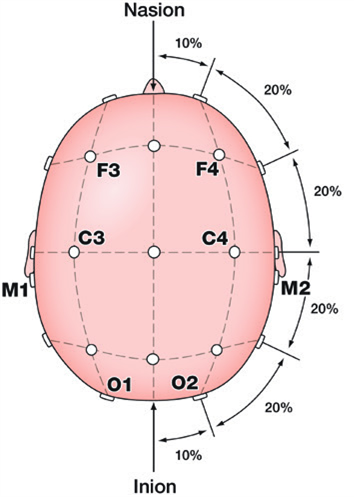

Load the data and see how it is structured

% load data
cd(mydata)
myfiles = dir('A_Preprocessed_90min_*.mat')
load(fullfile(myfiles.folder, myfiles.name));

disp(EEG90)

% What dimensions do you have?
dims = size(EEG90.data)
disp(['Number of timepoints: ', num2str(dims(2))]);
disp(['Number of channels: ', num2str(dims(1))]);

% How long are we?
fs = EEG90.srate;
npnts   = EEG90.pnts;
nhours  = npnts/fs/60/60;
disp(['Duration of recording: ',num2str(nhours),' h'])

Remove "outer ring" electrodes from the average reference as those are usually quite noisy

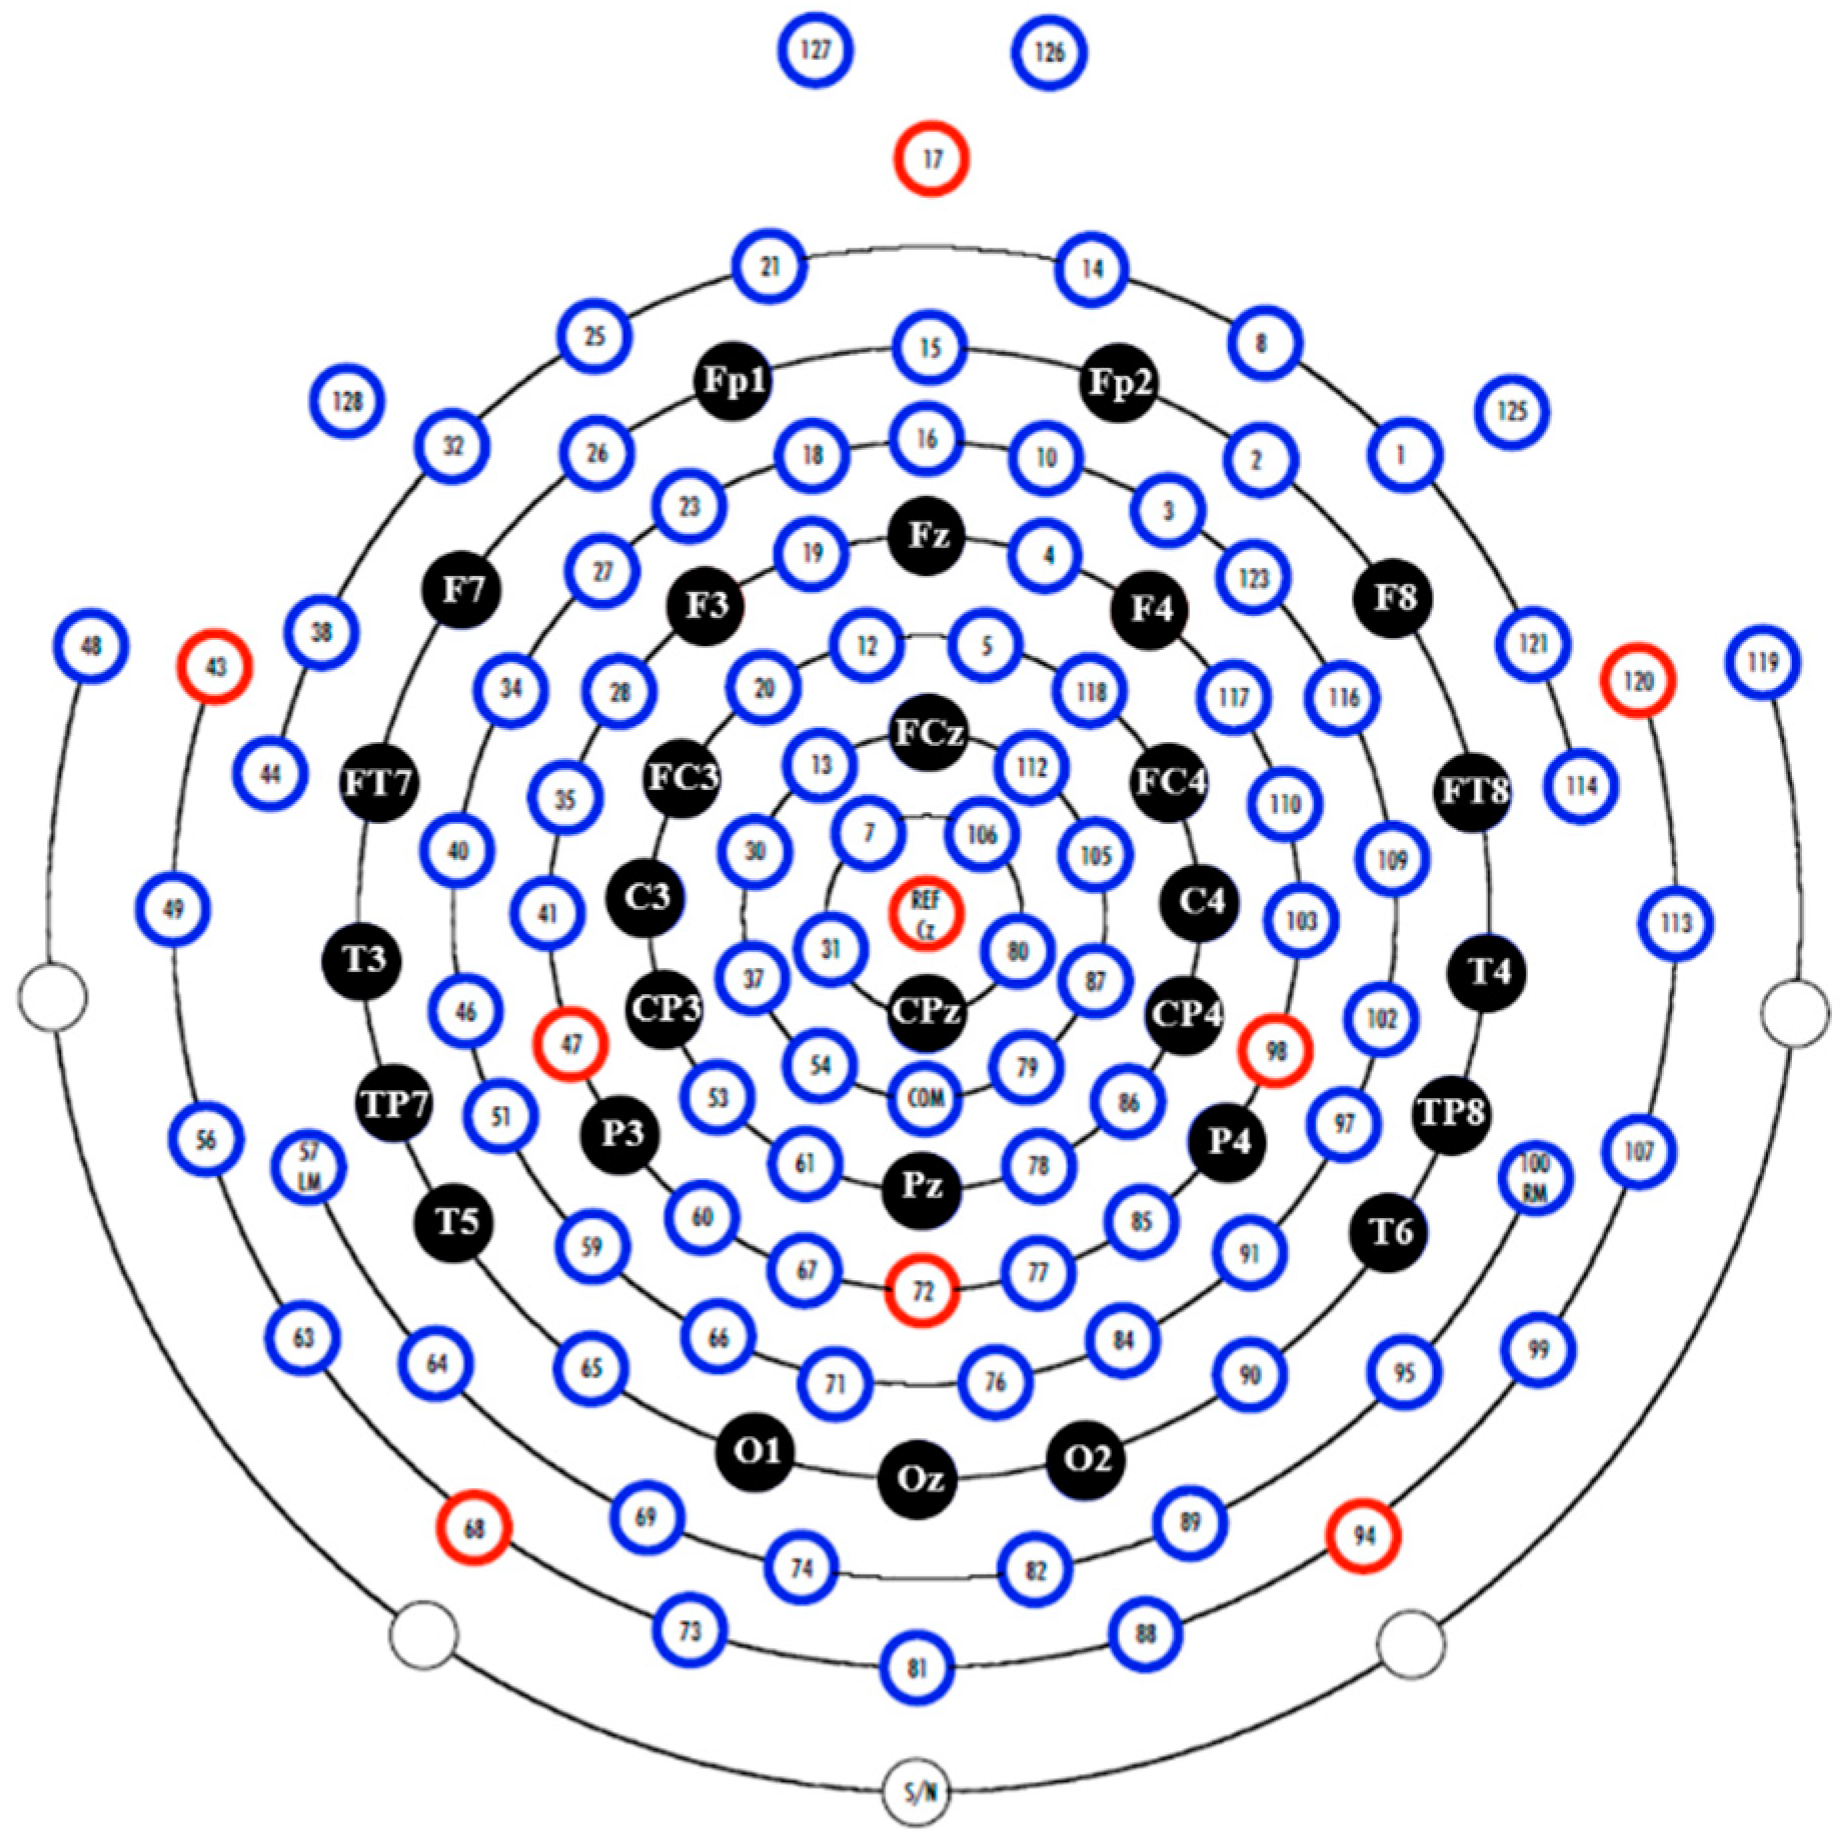

% remove outer ring
chansID = 1:128;
chansAVG = setdiff(chansID, [43, 48, 49, 56, 63, 68, 73, 81, 88, 94, 99, 107, 113, 119, 120, 125, 126, 127, 128]); %index of all channels EXCEPT outer ring

% mastoids
idxm1 = 57; %left mastoid
idxm2 = 100; %right mastoid

A) Re-reference to linked mastoids

data = EEG90.data;
datam = data - mean(data([idxm1,idxm2], :), 1, 'omitnan');
EEG90_M1M2 = EEG90;
EEG90_M1M2.data = datam;

% save re-referenced data
fileparts = strsplit(myfiles.name, '_');
basename = strjoin(fileparts(4:end),'_');
save(fullfile(mydata,['B_Rereferenced_Mastoids_',basename]),'EEG90_M1M2','-v7.3')

B) Re-reference to average reference

dataavg = data - mean(data(chansAVG, :), 1, 'omitnan');
EEG90_AVG = EEG90;
EEG90_AVG.data = dataavg;
% save re-referenced data
save(fullfile(mydata,['B_Rereferenced_Average_',basename]),'EEG90_AVG','-v7.3')

## --- DONE WITH FIRST PART! ---

For those who are interested in reproducing the filters used for preprocessing, here is a script to visualize them

% design the Low-Pass Filter

% FIR filter 35 Hz - kaiser (attenuated 50 Hz perfectly)
srateFilt    = fs;
passFrq      = 30;
stopFrq      = 49.75;
passRipple   = 0.02;
stopAtten    = 60;
LoPassFilt   = designfilt('lowpassfir','PassbandFrequency',passFrq,'StopbandFrequency',stopFrq,'PassbandRipple',passRipple,'StopbandAttenuation',stopAtten, 'SampleRate',srateFilt, 'DesignMethod','kaiser','MinOrder','Even');

% Plot the filter in time and in frequency domain (will get to understand
% the specifics later)
lpfiltkern = LoPassFilt.Coefficients;
lpfiltpow = abs(fft(lpfiltkern)).^2;

% compute the frequencies vector and remove negative frequencies
hz      = linspace(0,fs/2,floor(length(lpfiltkern)/2)+1);
lpfiltpow = lpfiltpow(1:length(hz));

figure(1), clf
subplot(121)
plot(lpfiltkern,'linew',2)
xlabel('Time points')
title('Filter kernel')
axis square

% plot power spectrum of the filter kernel
subplot(122), hold on
plot(hz,lpfiltpow,'k-','linew',2)

% make the plot look nicer
set(gca,'xlim',[0 80])
xlabel('Frequency (Hz)'), ylabel('Filter gain')
title('Frequency response of filter')
axis square


% design the High-Pass Filter

% FIR filter 0.5 Hz - kaiser (removes low frequency artifacts and DC offset when combined with the EGI filter)
srateFilt  = fs;
passFrq    = 0.5;
stopFrq    = 0.25;
passRipple = 0.05;
stopAtten  = 30;
HiPassFilt = designfilt('highpassfir','PassbandFrequency',passFrq,'StopbandFrequency',stopFrq,'StopbandAttenuation',stopAtten,'PassbandRipple',passRipple,'SampleRate',srateFilt,'DesignMethod','kaiser','MinOrder','Even');

% Plot the filter in time and in frequency domain (will get to understand
% the specifics later)
hpfiltkern = HiPassFilt.Coefficients;
hpfiltpow = abs(fft(hpfiltkern)).^2;

% compute the frequencies vector and remove negative frequencies
hz      = linspace(0,fs/2,floor(length(hpfiltkern)/2)+1);
hpfiltpow = hpfiltpow(1:length(hz));

figure(2), clf
subplot(121)
plot(hpfiltkern,'linew',2)
xlabel('Time points')
title('Filter kernel')
axis square

% plot power spectrum of the filter kernel
subplot(122), hold on
plot(hz,hpfiltpow,'k-','linew',2)

% make the plot look nicer
set(gca,'xlim',[0 30])
xlabel('Frequency (Hz)'), ylabel('Filter gain')
title('Frequency response of filter')
axis square